Coeff_lat = load("pacejka_coefficients_lateral.mat").C;
Coeff_long = load("pacejka_coefficients_longitudinal.mat").C;

Lateral plots

alpha = linspace(-pi/2+0.1,pi/2-0.1,100)

alpha =    -1.4708   -1.4411   -1.4114   -1.3817   -1.3519   -1.3222   -1.2925   -1.2628   -1.2331   -1.2034   -1.1737   -1.1440   -1.1142   -1.0845   -1.0548   -1.0251   -0.9954   -0.9657   -0.9360   -0.9062   -0.8765   -0.8468   -0.8171   -0.7874   -0.7577   -0.7280   -0.6983   -0.6685   -0.6388   -0.6091   -0.5794   -0.5497   -0.5200   -0.4903   -0.4606   -0.4308   -0.4011   -0.3714   -0.3417   -0.3120   -0.2823   -0.2526   -0.2228   -0.1931   -0.1634   -0.1337   -0.1040   -0.0743   -0.0446   -0.0149


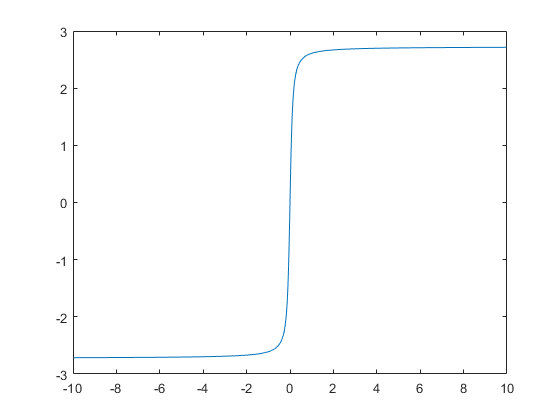

sigma_y = tan(alpha);
mu = pacejka(Coeff_lat(1,:), sigma_y);
plot(sigma_y,mu)

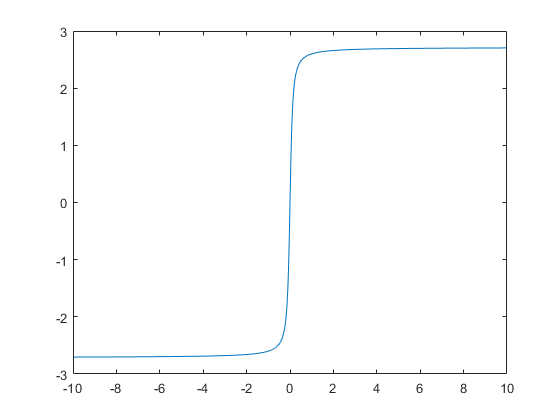

figure
mu = pacejka(Coeff_lat(2,:), sigma_y);
plot(sigma_y,mu)

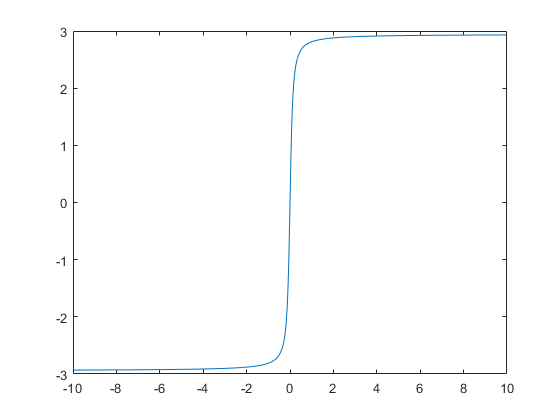

figure
mu = pacejka(Coeff_lat(3,:), sigma_y);
plot(sigma_y,mu)

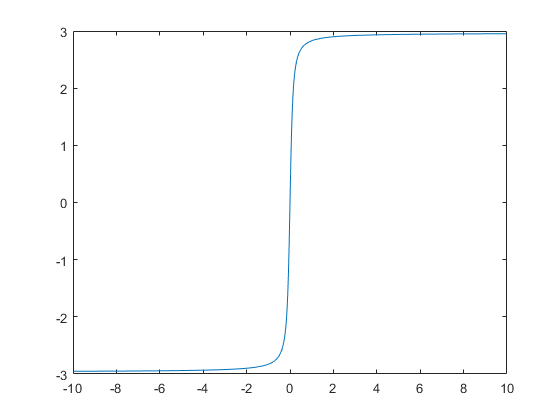

figure
mu = pacejka(Coeff_lat(4,:), sigma_y);
plot(sigma_y,mu)

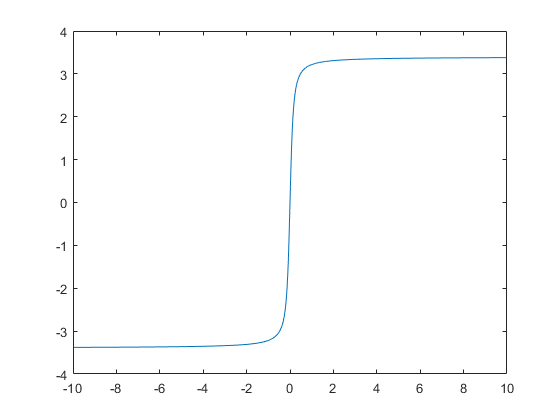

figure
mu = pacejka(Coeff_lat(5,:), sigma_y);
plot(sigma_y,mu)

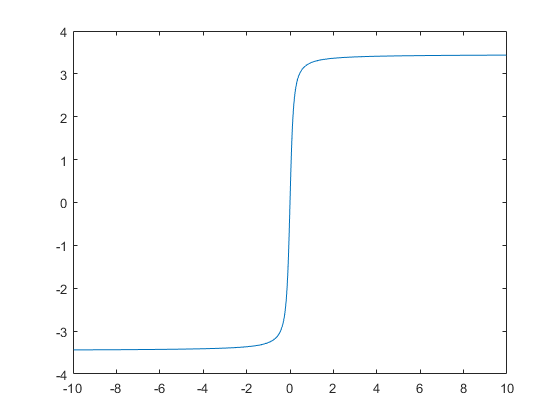

figure
mu = pacejka(Coeff_lat(6,:), sigma_y);
plot(sigma_y,mu)

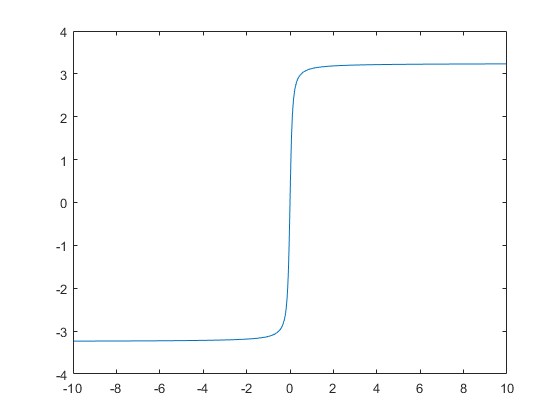

figure
mu = pacejka(Coeff_lat(7,:), sigma_y);
plot(sigma_y,mu)

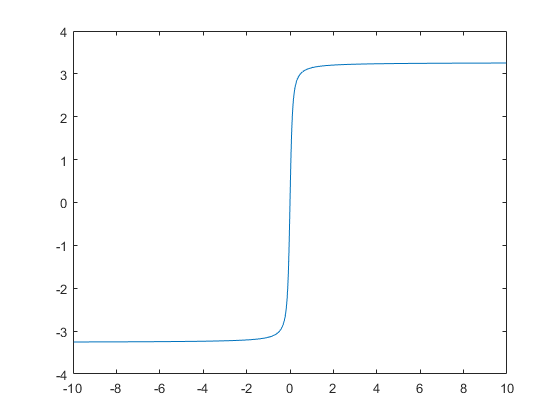

figure
mu = pacejka(Coeff_lat(8,:), sigma_y);
plot(sigma_y,mu)

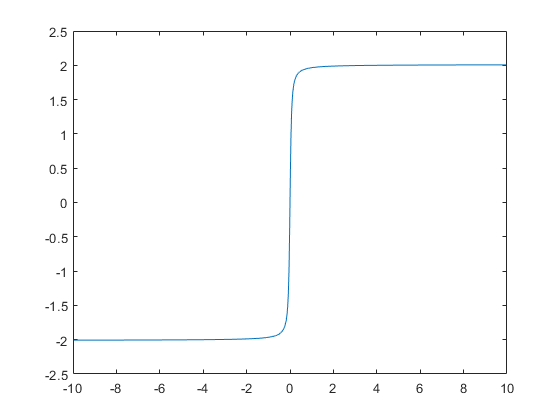

figure
mu = pacejka(Coeff_lat(9,:), sigma_y);
plot(sigma_y,mu)

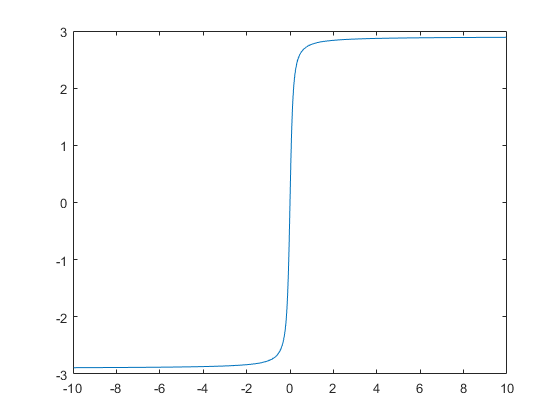

figure
mu = pacejka(Coeff_lat(10,:), sigma_y);
plot(sigma_y,mu)

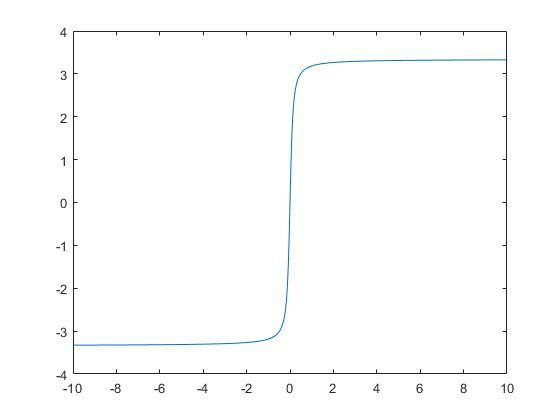

figure
mu = pacejka(Coeff_lat(11,:), sigma_y);
plot(sigma_y,mu)

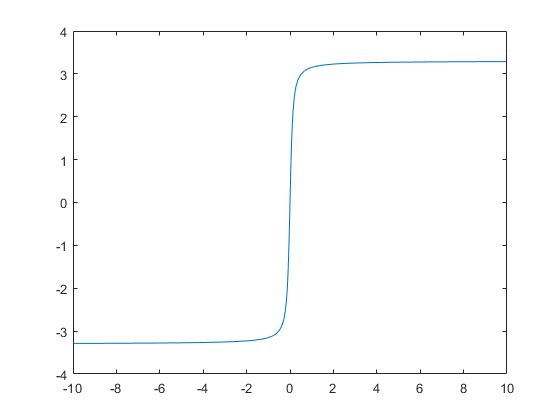

figure
mu = pacejka(Coeff_lat(12,:), sigma_y);
plot(sigma_y,mu)

figure

Longitudinal plots

kappa = linspace(-1,1,100)

kappa =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


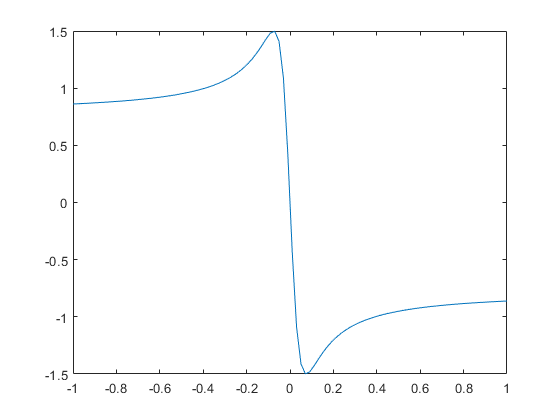

%sigma_x = kappa./(1+kappa);
sigma_x = kappa;
mu = pacejka(Coeff_long(1,:), sigma_x);
plot(kappa,mu)

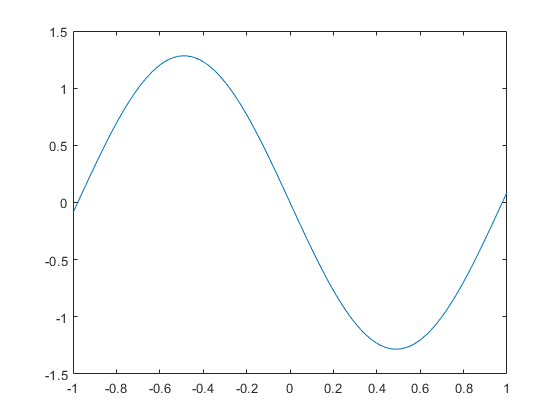

figure
mu = pacejka(Coeff_long(2,:), sigma_x);
plot(kappa,mu)

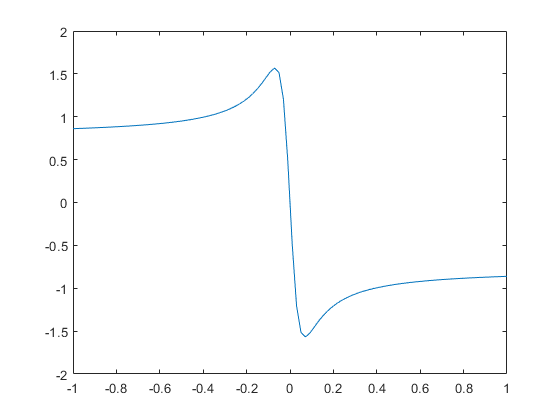

figure
mu = pacejka(Coeff_long(3,:), sigma_x);
plot(kappa,mu)

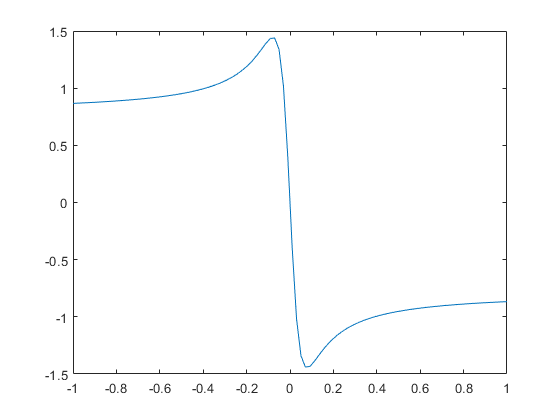

figure
mu = pacejka(Coeff_long(4,:), sigma_x);
plot(kappa,mu)

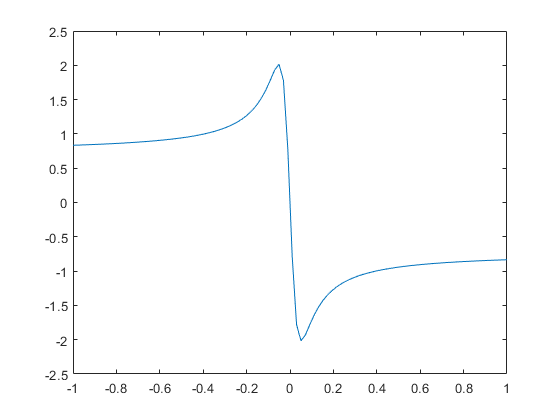

figure
mu = pacejka(Coeff_long(5,:), sigma_x);
plot(kappa,mu)

Pacejka function:

function y = pacejka(C,sigma)
    y=C(3)*sin(C(2)*atan(atan(C(1)*sigma)));
end